# Plan Optimal Path Between Two States

Create a state space.

ss = stateSpaceSE2;

Create a `occupancyMap`-based state validator using the created state space.

sv = validatorOccupancyMap(ss);

Create an occupany map from an example map and set map resolution as 10 cells/meter.

%load exampleMaps.mat
load testmap.mat
%map = occupancyMap(simpleMap, 10);
sv.Map = map;

Set validation distance for the validator.

sv.ValidationDistance = 0.01;

Update state space bounds to be the same as map limits.

ss.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];

 Create RRT* path planner and allow further optimization after goal is reached.

planner = plannerRRTStar(ss,sv);
planner.ContinueAfterGoalReached = true;

Reduce max iterations and increase max connection distance.

planner.MaxIterations = 2500;
planner.MaxConnectionDistance = 0.3;

Set the start and goal states. 

%start = [0.5, 0.5 0];
%goal = [2.5, 0.2, 0];

start = [-6.0, -2.5, -pi]; 
goal = [10, -1.0, 0];

Plan a path with default settings.

rng(100, 'twister') % repeatable result
[pthObj, solnInfo] = plan(planner,start,goal);

Visualize the results.

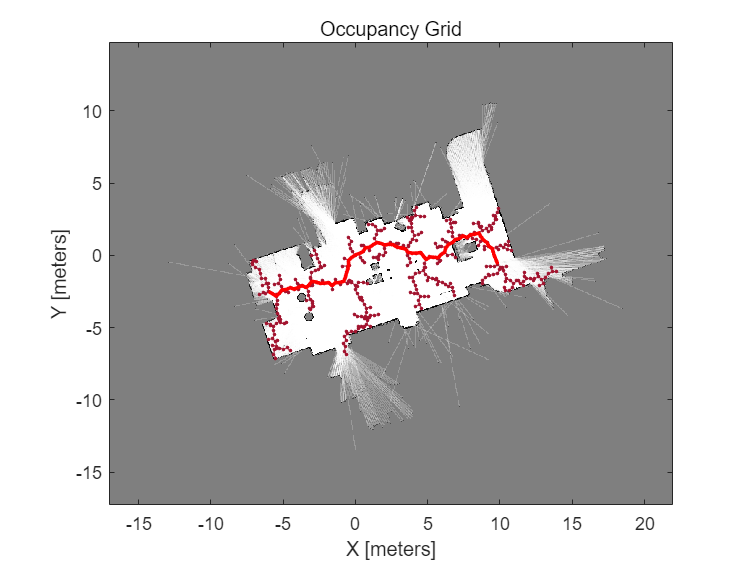

map.show;
hold on;
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2), '.-'); % tree expansion
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2); % draw path

*Copyright 2019 The MathWorks, Inc.*